warning off
data = readtable('C:\Users\malee\Downloads\archive\voice.csv')

data = 3168×21 table
    meanfreq       sd        median        Q25         Q75         IQR        skew       kurt     sp_ent       sfm        mode      centroid    meanfun      minfun     maxfun      meandom      mindom       maxdom       dfrange     modindx      label  
    ________    ________    ________    _________    ________    ________    _______    ______    _______    _______    ________    ________    ________

DataC=data;
 %Checking the Null values
 disp(sum(ismissing(data)));

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



 % Labeling our data with (1 for Male and 0 for Female) 
k=["male","female"];
 l=[1,0];
 g=DataC.label;
 % generete vector of 0 and 1 values 
number=zeros(length(g),1);
 for i=1:length(k)
 rs=ismember(g,k(i)); number(rs)=l(i);
 end
 DataC.label=number;

 %Dividing data into train & test set
 cv = cvpartition(size(DataC,1),'HoldOut',0.2);
 idx = cv.test;
 % Separate to training and test data
 dataTrain = DataC(~idx,:);
 Training_Data=dataTrain(:,1:end-1);
 Class_Label_Training=dataTrain(:,end);
 dataTest = DataC(idx,:);
 Testing_Data=dataTest(:,1:end-1);
 Class_Label_Testing=dataTest(:,end);
 %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
 %Standardization of Training data
 m = table2array(Training_Data);
 meanArray = mean(m);
 stdArray = std(m);
 zam= (m - meanArray) ./ stdArray;
 Training_Data = array2table(zam, 'VariableNames',{'meanfreq' 'sd' 'median'...
 'Q25' 'Q75' 'IQR' 'skew' 'kurt' 'sp_ent' ...
 'sfm' 'mode' 'centroid' 'meanfun' 'minfun' 'maxfun' ...
 'meandom' 'mindom' 'maxdom' 'dfrange' 'modindx'});
 dataTrain=[Training_Data Class_Label_Training];

  %Standardization of Test data
 m = table2array(Testing_Data);
 meanArray = mean(m)

meanArray =     0.1808    0.0577    0.1858    0.1401    0.2253    0.0852    3.1913   37.0409    0.8947    0.4094    0.1623    0.1808    0.1427    0.0364    0.2581    0.8257    0.0509    5.0572    5.0063    0.1691


 stdArray = std(m)

stdArray =     0.0297    0.0171    0.0366    0.0492    0.0229    0.0446    4.2943  131.1855    0.0470    0.1815    0.0802    0.0297    0.0326    0.0191    0.0307    0.5429    0.0626    3.6074    3.6041    0.1079


 Testing_Data= (m - meanArray) ./ stdArray;
 Testing_Data = array2table(Testing_Data,'VariableNames',{'meanfreq' 'sd' 'median'...
 'Q25' 'Q75' 'IQR' 'skew' 'kurt' 'sp_ent' ...
 'sfm' 'mode' 'centroid' 'meanfun' 'minfun' 'maxfun' ...
 'meandom' 'mindom' 'maxdom' 'dfrange' 'modindx'});
 dataTest=[Testing_Data Class_Label_Testing];

 %Training the model
 K=3;
 % modelformed=fitcknn(dataTrain,'label');
 modelformed=fitcknn(Training_Data,Class_Label_Training, 'NumNeighbors',K);
 %Accuracy with default model parameters
 mk=predict(modelformed,Testing_Data);
 accuracy_check=((sum((mk==table2array(dataTest(:,end)))))/size(dataTest,1))*100;
 disp(accuracy_check);

   97.3144



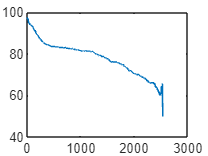

 %Running KNN for every possible value on this dataset
 accuracy=[];
 k=1;
 for i=1:size(dataTrain,1)
 modelformed=fitcknn(Training_Data,Class_Label_Training,'NumNeighbors',k);
 modelformed.NumNeighbors=i;
 mk=predict(modelformed,Testing_Data);
 accuracy_check=((sum((mk==table2array(dataTest(:,end)))))/size(dataTest,1))*100;
 accuracy=[accuracy accuracy_check];
 end
 %Plot 
plot((1:size(dataTrain,1)),accuracy);